## 선형제어시스템 Report


$$\dot{\;X} =\textrm{AX}+\textrm{Bu}$$


A = [0,  0,  0,    1,    0,    0;...
     0,  0,  0,    0,    1,    0;...
     0,  0,  0,    0,    0,    1;...
     -2, 1,  0, -1.6,  0.8,    0;...
     1, -2,  1,  0.8, -1.6,  0.8;...
     0,  1, -1,    0,  0.8, -0.8];

B = [0, 0, 0, 1, 0, 0]';

% 구현한 controllability matrix
CM = [B, A*B, A^2*B, A^3*B, A^4*B, A^5*B];
disp(CM);

         0    1.0000   -1.6000    1.2000    0.8320   -4.6768
         0         0    0.8000   -1.5600    0.7680    3.6288
         0         0         0    0.6400   -0.9600   -0.8176
    1.0000   -1.6000    1.2000    0.8320   -4.6768    9.4899
         0    0.8000   -1.5600    0.7680    3.6288  -11.8656
         0         0    0.6400   -0.9600   -0.8176    5.2851



Co  = ctrb(A,B);
disp(Co);

         0    1.0000   -1.6000    1.2000    0.8320   -4.6768
         0         0    0.8000   -1.5600    0.7680    3.6288
         0         0         0    0.6400   -0.9600   -0.8176
    1.0000   -1.6000    1.2000    0.8320   -4.6768    9.4899
         0    0.8000   -1.5600    0.7680    3.6288  -11.8656
         0         0    0.6400   -0.9600   -0.8176    5.2851



주어진 A와 B를 통해 작성한 controllability와 built-in 함수로 확인한 controllability matrix가 동일한 것을 확인할 수 있다.

rank_CM = rank(CM);
fprintf('rank(Co) = %d (n = %d)\n', rank_CM, size(A,1));

rank(Co) = 6 (n = 6)


따라서 구현한 controllability matrix `CM `의 rank 확인을 통해 해당 시스템은 모든 상태에 대해 제어가 가능한 시스템임을 확인할 수 있다.

### 무한 시간 controllability Gramian

`A`가 안정이면 Lyapunov function으로 `W_c`를 해석적으로 계산이 가능하다.

Wc = lyap(A, B*B');
eig_Wc = eig(Wc);
fprintf('무한-시간 Gramian 최소 고유값 = %.3e\n', min(eig_Wc));

무한-시간 Gramian 최소 고유값 = 3.948e-04


### 9.5초 내 제어 요구 조건을 충족하는 최적 input $u$

T = 9.5;
dt = 1e-3;
x_f = [1, 2, 3, 0, 0, 0]';
% Desired state xf

모든 상태를 관측할 수 있다고 가정하였다. 즉,

C = diag(ones([1, 6]));
D = 0;
system = ss(A, B, C, D);

Gramian 계산

Wc = zeros(6);
time = 0:dt:T;
for t = time
    E = expm(A * t);
    Wc = Wc + E*B*B'*E'*dt;
end

최적 input `u_opt` 계산

u_opt = zeros(size(time));
inv_Wc = Wc\eye(length(Wc));
for k = 1:length(time)
    t = time(k);
    E = expm(A'*(T - t));
    u_opt(k) = B' * E * inv_Wc * x_f;
end

시뮬레이션 초기화

x = zeros([6, 1]);
sim_time = 0:dt:T;
odefcn = @(t, x) A*x + B*interp1(sim_time, u_opt, t);
[sim_t, sim_x] = ode45(odefcn, sim_time, x);

**결과 출력**

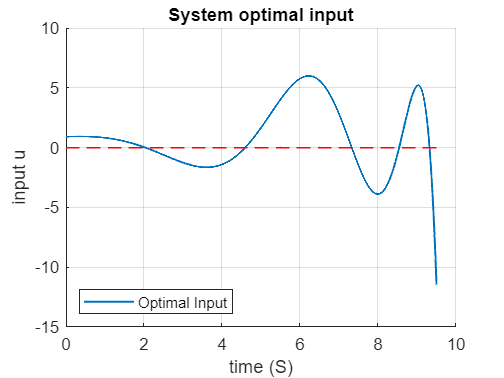

ioLineWidth = 1.2;

optimSysInput = figure();
hold on; grid on;
sysInput = plot(sim_time, u_opt, "LineWidth",ioLineWidth);
zeroLine = plot(sim_time, zeros([length(sim_time), 1]), "r--", "LineWidth", ioLineWidth);
xlabel("time (S)"); ylabel("input u"); title("System optimal input");
legend(sysInput, "Optimal Input", "Location", "southwest");

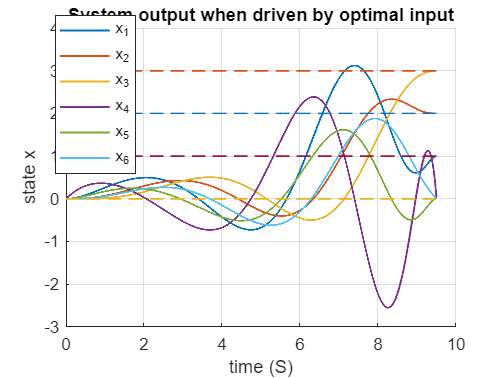


sysOutput = figure();
hold on; grid on;
x1 = plot(sim_time, sim_x(:,1), "LineWidth",ioLineWidth);
x2 = plot(sim_time, sim_x(:,2), "LineWidth",ioLineWidth);
x3 = plot(sim_time, sim_x(:,3), "LineWidth",ioLineWidth);
x4 = plot(sim_time, sim_x(:,4), "LineWidth",ioLineWidth);
x5 = plot(sim_time, sim_x(:,5), "LineWidth",ioLineWidth);
x6 = plot(sim_time, sim_x(:,6), "LineWidth",ioLineWidth);
xd_1 = plot(sim_time, 1*ones([length(sim_time), 1]), "--", "LineWidth", ioLineWidth);
xd_2 = plot(sim_time, 2*ones([length(sim_time), 1]), "--", "LineWidth", ioLineWidth);
xd_3 = plot(sim_time, 3*ones([length(sim_time), 1]), "--", "LineWidth", ioLineWidth);
xd_456 = plot(sim_time, zeros([length(sim_time), 1]), "--", "LineWidth", ioLineWidth);
xlabel("time (S)"); ylabel("state x"); title("System output when driven by optimal input");
legend([x1, x2, x3, x4, x5, x6], {"x_1", "x_2", "x_3", "x_4", "x_5", "x_6"});
legend("Position", [0.14,0.6,0.1,0.3]);